# Tune a PID Controller for a Plant Using Live Editor Tasks

This example shows how to tune a PID controller for a plant whose model is assumed to be estimated as a continous-time state space model from measured plant data.

## Load and Examine the State-Space Model

We assume that a plant model is identified from measured input-output data that consists of the response of an engine to a chirp input.  First, load the identified state-space model and take a look at its frequency response using a Bode plot.

load identifiedModel.mat 
identifiedModel

identifiedModel =
 
  A = 
            x1       x2       x3       x4
   x1   -1.803    1.849    5.042  -0.6817
   x2   0.2444   0.2121   -17.12   -1.206
   x3  -0.6176    1.988   -8.676    39.97
   x4  -0.1647    1.513   -37.01    4.307
 
  B = 
           u1
   x1   21.36
   x2  -73.35
   x3   70.24
   x4  -139.4
 
  C = 
           x1      x2      x3      x4
   y1   16.74  0.7304  0.3357    1.11
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


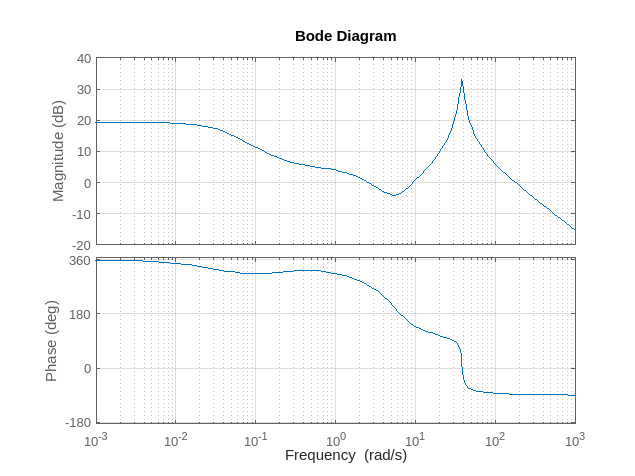

bode(identifiedModel)
grid on

## Discretize the Model

Now we want to design a PID controller with sample time 0.025 s.  First we need to discretize the plant model to this sample time.  The discretized model should accomodate the resonance in the identified model response and match the frequency response in the vicinity of the resonance.  Here, we'll use the ***Convert Model Rate*** Live Editor Task to get a discretized model that matches the identified model as closely as possible.

After some experimentation, it looks like the Bilinear (Tustin) approximation with a prewarp frequency of 38.4 rad/s gives a discrete model with a good match of the frequency response in the vicinity of the resonance.  The new discrete model is in the variable `discreteModel`.

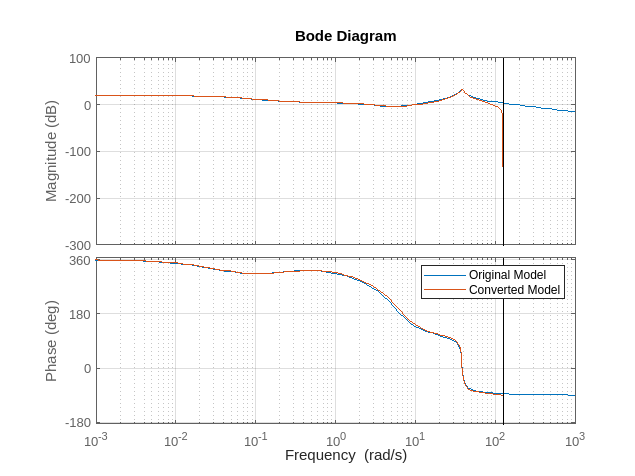

% Create option set for continuous to discrete-time conversion
options2 = c2dOptions('Method','tustin','PrewarpFrequency',38.4);

% Convert model from continuous to discrete time
discreteModel = c2d(identifiedModel,0.025,options2);

% Remove temporary variables from Workspace
clear options2

% Visualize the results
bodeplot(identifiedModel,discreteModel);
legend('Original Model','Converted Model');
grid on;

To confirm that the discretized model captures the transient response due to the resonance, compare the first few seconds of the step responses of the original identified model `identifiedModel` and the discretized model `discreteModel`. 

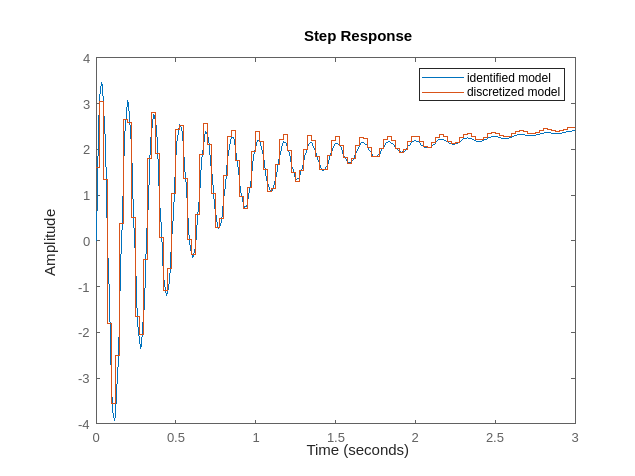

step(identifiedModel,discreteModel,3)
legend({'identified model','discretized model'})

## Tune Controller for Discretized Plant Model

The last step is to tune a PID controller for the discretized plant model.  Here we will assume the standard unit-feedback control configuration shown in the picture below.

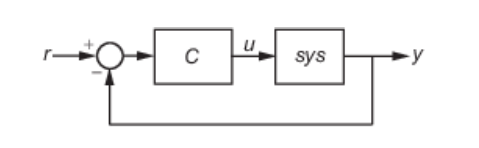

We will use the ***Tune PID Controller*** Live Editor Task to experiment with settings such as controller type and response time.  We would like to get a closed-loop system that will settle within 15 seconds with an overshoot of no more than 20%.

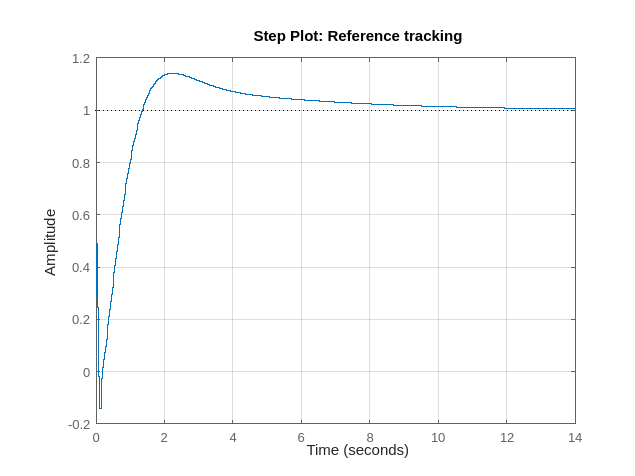

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/1.5;

% PID tuning algorithm for linear plant model
[pidController,pidInfo] = pidtune(discreteModel,'PI',wc);

% Clear Temporary Variables
clear wc

% Get desired loop response
Response = getPIDLoopResponse(pidController,discreteModel,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response

pidController

pidController =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 0.251, Ki = 0.832, Ts = 0.025
 
Sample time: 0.025 seconds
Discrete-time PI controller in parallel form.
Model Properties


Copyright (c) 2019, The MathWorks, Inc.